Declaration of variables

clc;
clear;

Road_length = 100;
car_number   = 10

car_number = 10

acceleration =5

acceleration = 5

deceleration =-3

deceleration = -3

%initial speed
u = 5

u = 5

%time limitis
time = 100

time = 100

%limit speed
lim = 15

lim = 15

%initial position of car
J = 1:car_number

J =      1     2     3     4     5     6     7     8     9    10


A = rand(1,car_number).*Road_length

A =    65.9605   51.8595   97.2975   64.8991   80.0331   45.3798   43.2392   82.5314    8.3470   13.3171


x(J,1)= sort(A)

x =     8.3470
   13.3171
   43.2392
   45.3798
   51.8595
   64.8991
   65.9605
   80.0331
   82.5314
   97.2975


v(J,1)=randi([0,10],10,1)

v =      1
     4
     9
     8
     0
     4
     5
     4
     7
     6


%minimum distance between cars
x0 = Road_length/car_number

x0 = 10

num = car_number-1

num = 9

initialize road

for T=2:time
    for J=1:car_number
        if J == car_number
            dis(J,T) = 100 - x(J,T-1)+x(1,T-1);
        else
            dis(J,T) = x(J+1,T-1)-x(J,T-1);
        end
        if dis(J,T)<0
            dis(J,T) = 0;
        end
        if dis(J,T) > x0
           v(J,T)=v(J,T-1) + acceleration;
           if v(J,T)<0
           v(J,T)=0;
           end
           x(J,T)=x(J,T-1)+v(J,T);
        else
           v(J,T)=v(J,T-1)+ deceleration;
           if v(J,T)<0
           v(J,T)=0;
           end
           x(J,T)=x(J,T-1)+v(J,T);
        end
        if v(J,T)>lim
            v(J,T)=lim;
        end
        if x(J,T) > Road_length
           x(J,T)=x(J,T)- Road_length;
        end
    end
      max_speed(T) = max(v(J,T));
      min_speed(T) = min(v(J,T));
end



Plot

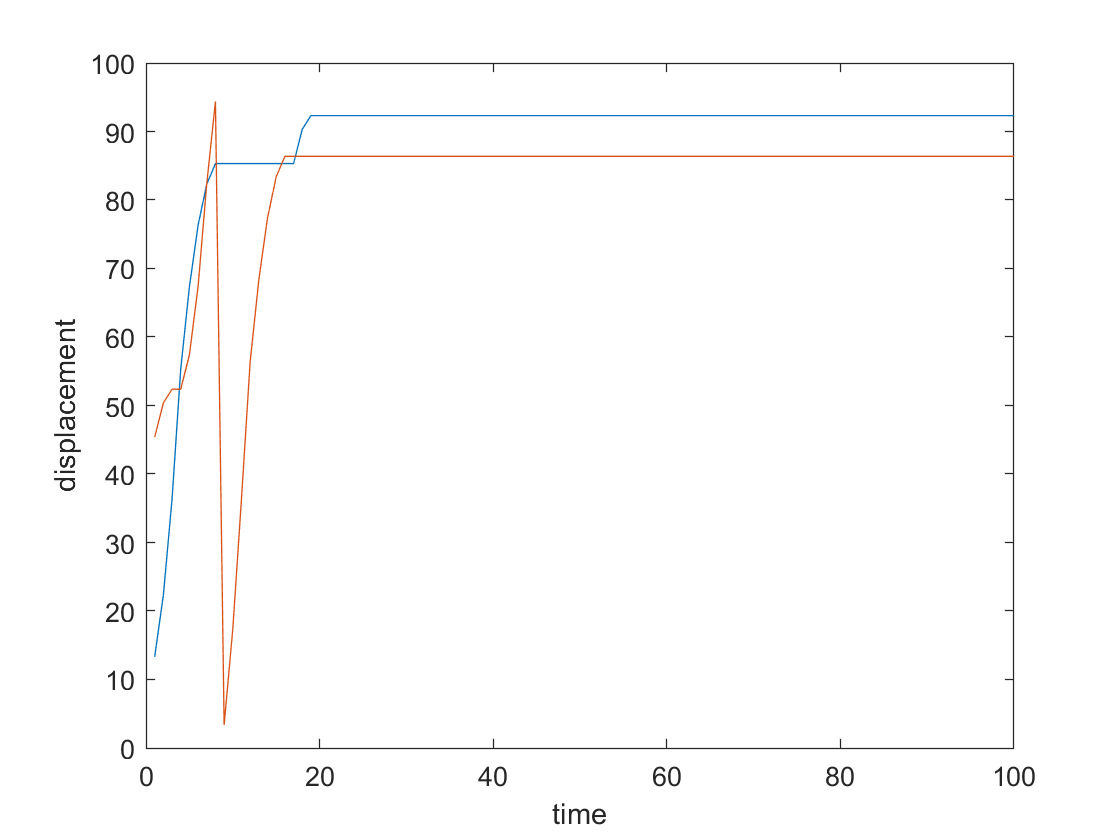

plot(x(2,:));
hold on;
plot(x(4,:));
xlabel('time')
ylabel('displacement')
hold off;

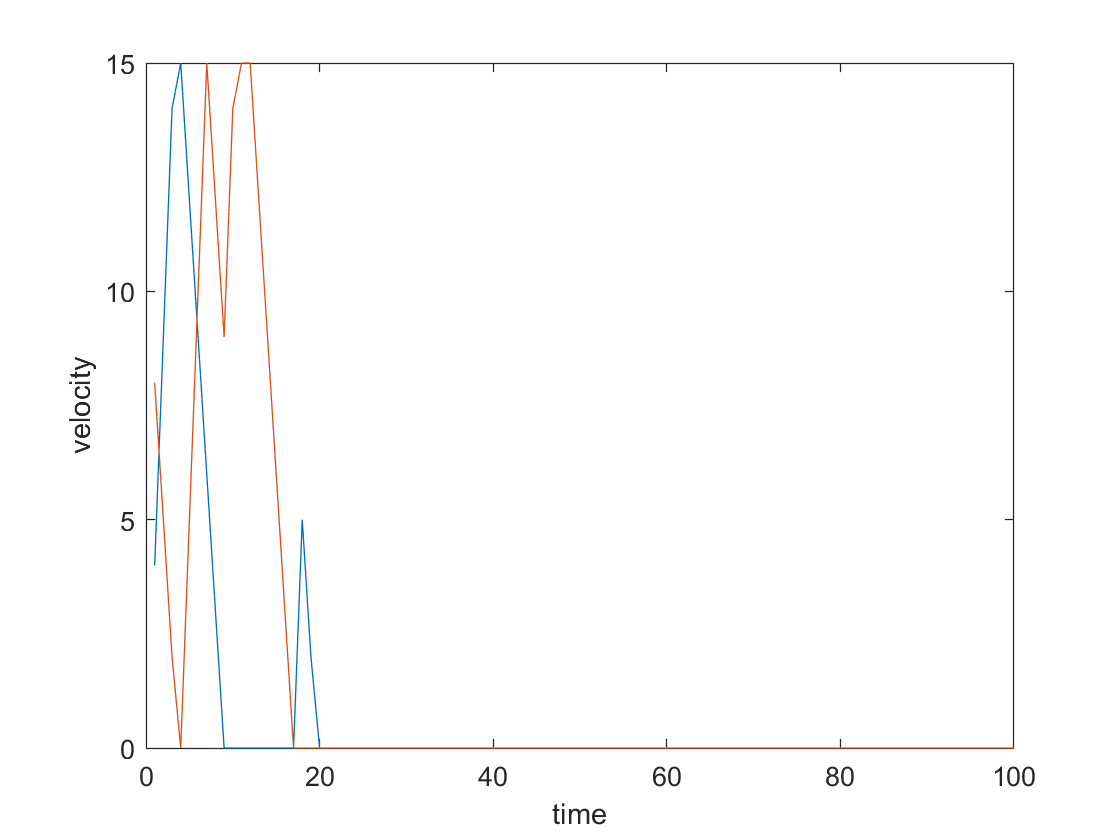

plot(v(2,:));
hold on;
plot(v(4,:));
xlabel('time')
ylabel('velocity')
hold off;

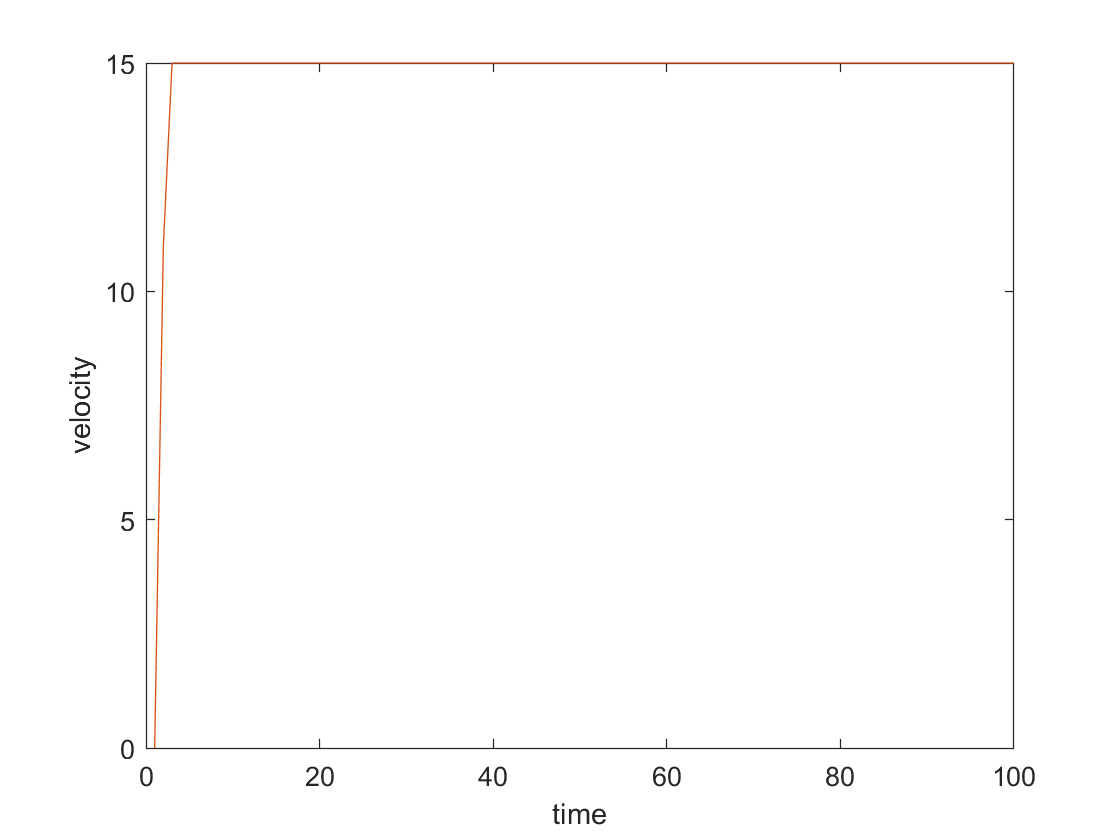

plot(max_speed);
hold on;
plot(min_speed);
xlabel('time')
ylabel('velocity')